syms r1 r2 c1 c2 t
a=[1/(r1*c1), -1/(r1*c1);1/(r1*c1) (r1+r2)/(r1*c2*r2)];
b=[1/(r1*c1),1/(r1*c2)]';
c=[1 0;0 1];
d=0;
xi=[1,1,-1]';
u=3.234*t-2.195*t^3+0.666*t^5;
xc=1;
sys=ss(a,b,c,d)

Error using ss (line 274)
The value of the "a" property must be a numeric array without any Inf's or NaN's.

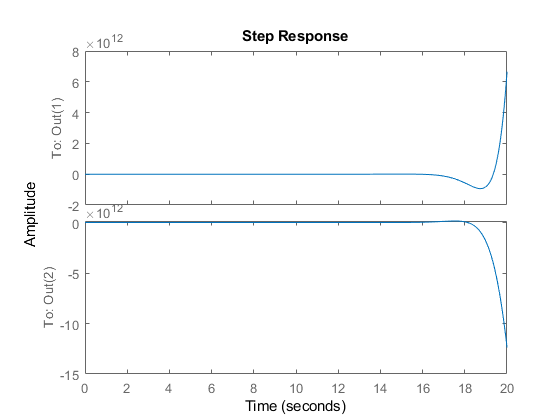

clc
clear all
a=[1 -1; 1 2];
b=[1 1]';
c=[1 0;0 1];
d=0;
sys=ss(a,b,c,d);
step(sys)

%clc
%clear all
syms t
a=[1 -1; 1 2];
b=[1 1]';
c=[1 0;0 1];
d=0;
xi=[0,0]';
u=3.234*t-2.195*t^3+0.666*t^5;
eat=expm(a*t);
est=eat*xi;
tra=int(eat*b*u,0,t);
Res=est+tra

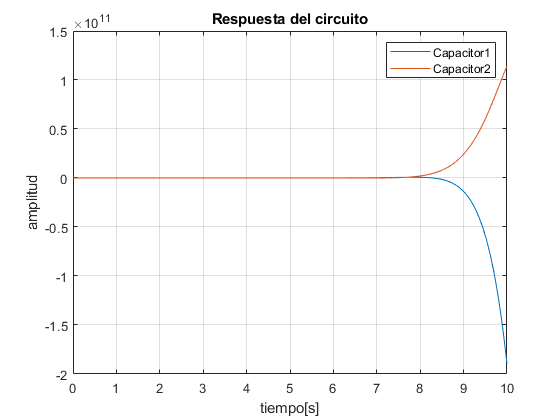

x=0:0.01:10;
comp=subs(Res,t,x);
%solucion=vpa(comp,6)

plot(x,comp)
xlabel('tiempo[s]');
ylabel('amplitud')
grid on
title('Respuesta del circuito')
legend('Capacitor1','Capacitor2')